# **Matlab案例代码解析**

## 7. 神经网络和机器学习案例

### 7.1 BP神经网络

#### 7.1.3 BP根据已有数据预测未知数据

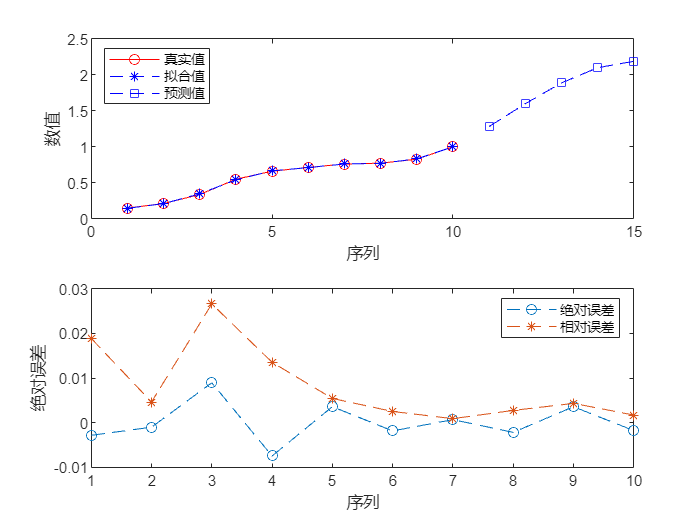

clear; clc;
% 原始数据
% data_ori = [320.9, 522.9309, 761.8405, 1205.9878, 1507.4308, 2013.3098, 3021.861, ...
%             4715.8742, 5621.8065, 6034.6872, 6412.2926, 6510.1012, 6954.24854, 8338]
% 处理后的数据，构建训练模型
data = [0         0.0252    0.0550    0.1104    0.1480
        0.0252    0.0550    0.1104    0.1480    0.2111
        0.0550    0.1104    0.1480    0.2111    0.3369
        0.1104    0.1480    0.2111    0.3369    0.5482
        0.1480    0.2111    0.3369    0.5482    0.6612
        0.2111    0.3369    0.5482    0.6612    0.7127
        0.3369    0.5482    0.6612    0.7127    0.7598
        0.5482    0.6612    0.7127    0.7598    0.7720
        0.6612    0.7127    0.7598    0.7720    0.8274
        0.7127    0.7598    0.7720    0.8274    1.0000];
minValue = 320.9;
maxValue = 8338;
[rowLen, colLen] = size(data);
train_num = rowLen;             % 训练样本数量
hidden_unit_num = 9;            % 隐含层
in_dim = colLen - 1;            % 输入层
out_dim = 1;                    % 输出层
p = data(:, 1:in_dim)';         % 输入数据矩阵
t = data(:, colLen)';           % 目标数据矩阵
% 归一化
[SamIn, PSp] = mapminmax(p, -1, 1);
[tn, PSt] = mapminmax(t, -1, 1);
SamOut = tn;         % 输出样本
MaxEpochs = 50000;   % 最大训练次数
lr = 0.05;           % 学习率
E0 = 1e-3;           % 目标误差
rng('default');
% 初始化权值、阈值
W1 = rand(hidden_unit_num, in_dim);      % 初始化输入层与隐含层之间的权值
B1 = rand(hidden_unit_num, 1);           % 初始化输入层与隐含层之间的阈值
W2 = rand(out_dim, hidden_unit_num);     % 初始化输出层与隐含层之间的权值              
B2 = rand(out_dim, 1);                   % 初始化输出层与隐含层之间的阈值
ErrHistory = zeros(MaxEpochs, 1);
%%%%%%% 训练
for i = 1 : MaxEpochs   
    HiddenOut = logsig(W1*SamIn + repmat(B1, 1, train_num));   % 隐含层网络输出
    NetworkOut = W2*HiddenOut + repmat(B2, 1, train_num);      % 输出层网络输出
    Error = SamOut - NetworkOut;       % 实际输出与网络输出之差
    SSE = sumsqr(Error);               % 能量函数（误差平方和）
    ErrHistory(i) = SSE;               % 记录每次学习的误差
    if SSE < E0                        % 如果达到误差阈值就退出
        break;
    end
    % 以下六行是BP网络最核心的程序
    % 权值（阈值）依据能量函数负梯度下降原理所作的每一步动态调整量
    Delta2 = Error;
    Delta1 = W2' * Delta2 .* HiddenOut .* (1 - HiddenOut);    
    dW2 = Delta2 * HiddenOut';
    dB2 = Delta2 * ones(train_num, 1); 
    dW1 = Delta1 * SamIn';
    dB1 = Delta1 * ones(train_num, 1);
    % 对输出层与隐含层之间的权值和阈值进行修正
    W2 = W2 + lr*dW2;
    B2 = B2 + lr*dB2;
    % 对输入层与隐含层之间的权值和阈值进行修正
    W1 = W1 + lr*dW1;
    B1 = B1 + lr*dB1;
end
% 隐含层输出最终结果
HiddenOut = logsig(W1*SamIn + repmat(B1, 1, train_num)); 
% 输出层输出最终结果
NetworkOut = W2*HiddenOut + repmat(B2, 1, train_num);      
% 反归一化
tFit = mapminmax('reverse', NetworkOut, PSt);
x = 1 : 10;   % 序列
subplot(2, 1, 1)
plot(x, t, 'r-o', x, tFit, 'b--*');
xlabel('序列');
ylabel('数值');
% 利用训练好的网络进行预测
% 滚动预测后续 5 年，每次预测 1 年
ForcastSamNum = 1;
preP = zeros(1, 5);
pNew = data(end, 2:end)';    % 最后一行是输入，竖着排
for i = 1 : 5
    pnew = pNew;  
    % 归一化，用学习数据的最大最小值
    pnewn = mapminmax('apply', pnew, PSp);
    HiddenOut = logsig(W1*pnewn + repmat(B1, 1, ForcastSamNum));  % 隐含层输出预测结果
    anewn = W2*HiddenOut + repmat(B2, 1, ForcastSamNum);          % 输出层输出预测结果
    % 反归一化
    anew = mapminmax('reverse', anewn, PSt);
    preP(i) = anew;      % 保存预测值
    pNew = [pNew(2:end); anew];   % 新预测的值作为下一次的输入
end
% 两条线画一起
hold on 
plot(11:15, preP, 'b--s');
legend('真实值', '拟合值', '预测值','Location','northwest');
hold off
subplot(2, 1, 2)
plot(x, tFit - t, '--o');
hold on
plot(x, abs(tFit - t) ./ t, '--*')
hold off
legend('绝对误差', '相对误差');
xlabel('序列');
ylabel('绝对误差');

% 真实值
realTfit = tFit * (maxValue - minValue) + minValue;
realPreP = preP * (maxValue - minValue) + minValue;
disp('预测值：');

预测值：


disp(realPreP);

   1.0e+04 *

    1.0590    1.3125    1.5446    1.7133    1.7857

